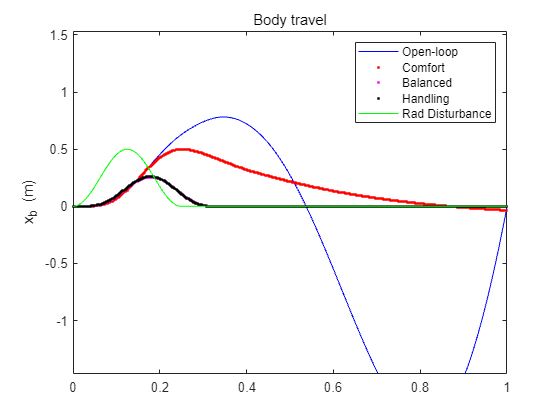

clear

mb = 300;
mw = 60;
bs = 1000;
ks = 16000;
kt = 190000;

A = [0 1 0 0; [-ks bs ks bs] / mb;
     0 0 0 1; [ks bs -ks-kt -bs] / mw];
B = [0 0; 0 1e3 / mb; 0 0; [kt -1e3] / mw];
C = [1 0 0 0; 1 0 -1 0; A(2, :)];
D = [0 0; 0 0; B(2, :)];
qcar = ss(A, B, C, D);

qcar.StateName = {'body travel(m)'; 'body vel(m/s)'; 'wheel trave(m)'; 'wheel vel(m/s)'};
qcar.InputName = {'r'; 'fs'};
qcar.OutputName = {'xb'; 'sd'; 'ab'};

ActNom = tf(1, [1/60, 1]);
ActNom.InputName = 'u';
ActNom.OutputName = 'fs';

Wroad = ss(0.07);
Wroad.u = 'd';
Wroad.y = 'r';
Wact = 0.8 * tf([1, 50], [1 500]);
Wact.u = 'u';
Wact.y = 'e1';

HandlingTarget = 0.004 * tf([1/8 1], [1/80 1]);
ComfortTarget = 0.4 * tf([1/0.45 1], [1/150 1]);

beta = reshape([0.01 0.5 0.99], [1 1 3]);
Wsd = beta / HandlingTarget;
Wsd.u = 'sd';
Wsd.y = 'e3';
Wab = (1 - beta) / ComfortTarget;
Wab.u = 'ab';
Wab.y = 'e2';

sdmeas = sumblk('y1 = sd');
abmeas = sumblk('y2 = ab');
ICinputs = {'d'; 'u'};
ICoutputs = {'e1'; 'e2'; 'e3'; 'y1'; 'y2'};
qcaric = connect(qcar(2 : 3, :), ActNom, Wroad, Wact, Wab, Wsd, sdmeas, abmeas, ICinputs, ICoutputs);

ncont = 1;
nmeas = 2;
K = ss(zeros(ncont, nmeas, 3));
gamma = zeros(3, 1);
for i = 1:3
     [K(:, :, i), ~, gamma(i)] = hinfsyn(qcaric(:, :, i), nmeas, ncont);
end

K.u = {'sd', 'ab'};
K.y = 'u';
CL = connect(qcar, ActNom, K, 'r', {'xb'; 'sd'; 'ab'});

t = 0 : 0.0025 : 1;
roaddist = zeros(size(t));
roaddist(1 : 101) = 0.25 * (1 - cos(8 * pi * t(1 : 101)));
p1 = lsim(qcar(:, 1), roaddist, t);
y1 = lsim(CL(1 : 3, 1, 1), roaddist, t);
y2 = lsim(CL(1 : 3, 1, 2), roaddist, t);
y3 = lsim(CL(1 : 3, 1, 3), roaddist, t);

plot(t, p1(:, 1), 'b', t, y1(:, 1), 'r.', t, y2(:, 1), 'm.', t, y3(:, 1), 'k.', t, roaddist, 'g');
title('Body travel');
ylabel('x_b (m)');
legend('Open-loop', 'Comfort', 'Balanced', 'Handling', 'Rad Disturbance', 'location', 'NorthEast');